# Calculo del Flux másico de transferencia de masa - Reline

Tabla de datos de Amphlett & Choi (2021)

Estos datos son temperatura ambiente aproximadamente 20°C (293.15 K).

water_content_Rel=[0;0;5;5;5];
coef_extincion_Rel=[0.013757;0.0056721;0.018619;0.0061803;0.0060692];
Temperature=293.15*ones(length(water_content_Rel),1);
concentr_Rel=1./coef_extincion_Rel;
table(Temperature,water_content_Rel,coef_extincion_Rel,concentr_Rel)

ans = 5×4 table
    Temperature    water_content_Rel    coef_extincion_Rel    concentr_Rel
    ___________    _________________    __________________    ____________

      293.15               0                 0.013757             72.69   
      293.15               0                0.0056721             176.3   
      293.15               5                 0.018619            53.709   
      293.15               5                0.0061803             161.8   
      293.15               5                0.0060692            164.77   


Cálculo de la densidad

Densidad_Rel= 1.2939+(-0.0012)*water_content_Rel+(-0.0006)*Temperature

Densidad_Rel =     1.1180
    1.1180
    1.1120
    1.1120
    1.1120


Cálculo de la densidad

Viscosidad_Rel=zeros(length(water_content_Rel),1);
% Importación de los datos sin outliers para ajuste del modelo
import_train_data=load("Data_Visc_Eth_NoOutliers.mat");
aux1=import_train_data.data1(:,1);
aux2=import_train_data.data1(:,2);
aux3=import_train_data.data1(:,3);
data_train_visc=[aux1 aux2 aux3];
data_train_visc=array2table(data_train_visc,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'});
% Llamado a la función del modelo seleccionado
[regre_visc_rel, ~] = MediumGaussianSVM_Visc_Ethaline(data_train_visc);

% Creacion del vector para predicción
aux_calc_viscosidad=[water_content_Rel Temperature Viscosidad_Rel];
aux_calc_viscosidad=array2table(aux_calc_viscosidad,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'});
% Cálculo de la viscosidad
Viscosidad_Rel=regre_visc_rel.predictFcn(aux_calc_viscosidad)

Viscosidad_Rel =    37.1533
   37.1533
   33.5364
   33.5364
   33.5364


Peso Molecular Promedio

% Datos de pesos moleculares como 2 componentes (Suma-->xiMi)
PM_Reline=87.92;
PM_Ethaline=91.22;
PM_Maline=136.85;
PM_water=18.02;
% Conversión de base de cálculo másica a molar
moles_Agua=water_content_Rel/PM_water;
moles_Ethaline=(100-water_content_Rel)/PM_Reline;
moles_totales=moles_Agua+moles_Ethaline;
fraccion_molar_agua=moles_Agua./moles_totales;
fraccion_molar_ethaline=moles_Ethaline./moles_totales;
% Cálculo del peso molecular de la mezcla
PM_Mezcla=fraccion_molar_agua*PM_water+fraccion_molar_ethaline*PM_Reline

PM_Mezcla =    87.9200
   87.9200
   73.6379
   73.6379
   73.6379


Volumen molar

Vol_molar=PM_Mezcla./Densidad_Rel

Vol_molar =    78.6397
   78.6397
   66.2205
   66.2205
   66.2205


Difusividad

fact_aso=1; % INPUT Factor de asociacion chi desde 1 hasta 2.6
% Cálculo del coeficiente de difusividad
Diff=(7.4e-8)*((fact_aso.^0.5*PM_Mezcla.^0.5.*Temperature)./(Viscosidad_Rel.*Vol_molar.^0.6))

Diff = 	1.0e+-6 *

    0.3990
    0.3990
    0.4485
    0.4485
    0.4485


Flux 

Flux=Diff.*concentr_Rel;

Resultado=table(Densidad_Rel, Viscosidad_Rel, PM_Mezcla, Vol_molar, Diff, Flux)

Resultado = 5×6 table
    Densidad_Rel    Viscosidad_Rel    PM_Mezcla    Vol_molar       Diff          Flux   
    ____________    ______________    _________    _________    __________    __________

       1.118            37.153          87.92        78.64      3.9901e-07    2.9004e-05
       1.118            37.153          87.92        78.64      3.9901e-07    7.0346e-05
       1.112            33.536         73.638        66.22       4.485e-07    2.4088e-05
       1.112            33.536         73.638        66.22       4.485e-07    7.2569e-05
       1.112            33.536         73.638        66.22       4.485e-07    7.3897e-05


Sensibilidades de factor de asociación chi desde 1 hasta 2.6

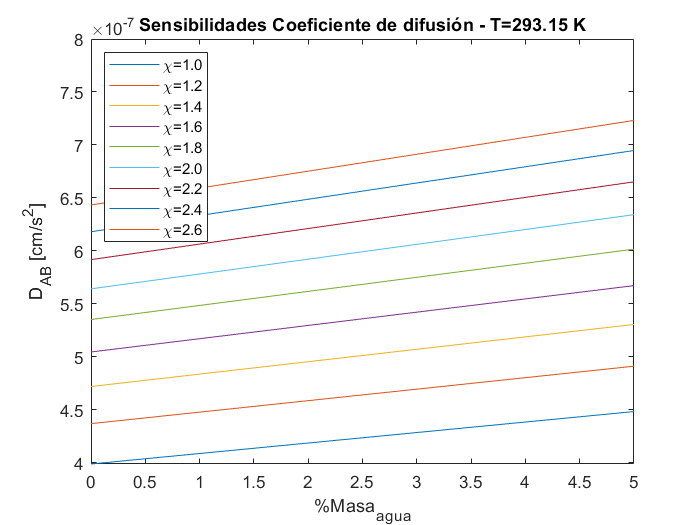

j=1;
for fact_aso=1:0.2:2.6
    Diff_sens(:,j)=(7.4e-8)*((fact_aso.^0.5*PM_Mezcla.^0.5.*Temperature)./(Viscosidad_Rel.*Vol_molar.^0.6));
    plot(water_content_Rel,Diff_sens(:,j)), hold on
    j=j+1; 
end
title('Sensibilidades Coeficiente de difusión - T=293.15 K')
xlabel('%Masa_a_g_u_a'), ylabel('D_A_B [cm/s^2]')
legend('\chi=1.0','\chi=1.2','\chi=1.4','\chi=1.6','\chi=1.8','\chi=2.0','\chi=2.2','\chi=2.4','\chi=2.6','Location','northwest')
hold off

Flux=Diff_sens.*concentr_Rel

Flux = 	1.0e+-3 *

    0.0290    0.0318    0.0343    0.0367    0.0389    0.0410    0.0430    0.0449    0.0468
    0.0703    0.0771    0.0832    0.0890    0.0944    0.0995    0.1043    0.1090    0.1134
    0.0241    0.0264    0.0285    0.0305    0.0323    0.0341    0.0357    0.0373    0.0388
    0.0726    0.0795    0.0859    0.0918    0.0974    0.1026    0.1076    0.1124    0.1170
    0.0739    0.0810    0.0874    0.0935    0.0991    0.1045    0.1096    0.1145    0.1192


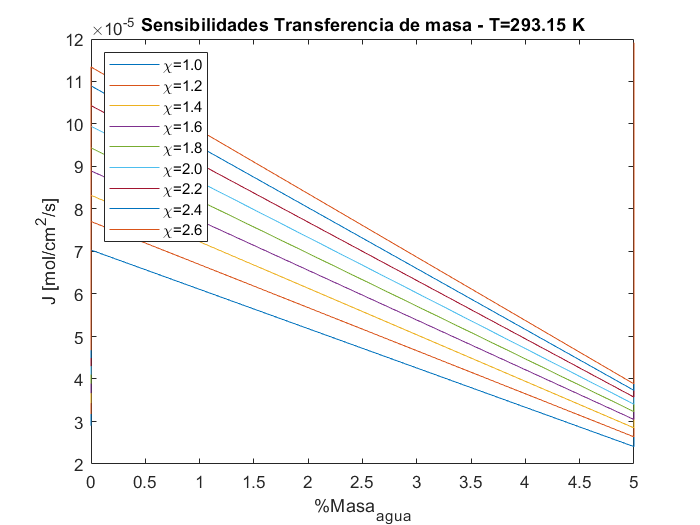


for k=1:9
    plot(water_content_Rel,Flux(:,k)), hold on 
end
title('Sensibilidades Transferencia de masa - T=293.15 K')
xlabel('%Masa_a_g_u_a'), ylabel('J [mol/cm^2/s]')
legend('\chi=1.0','\chi=1.2','\chi=1.4','\chi=1.6','\chi=1.8','\chi=2.0','\chi=2.2','\chi=2.4','\chi=2.6','Location','northwest')
hold off